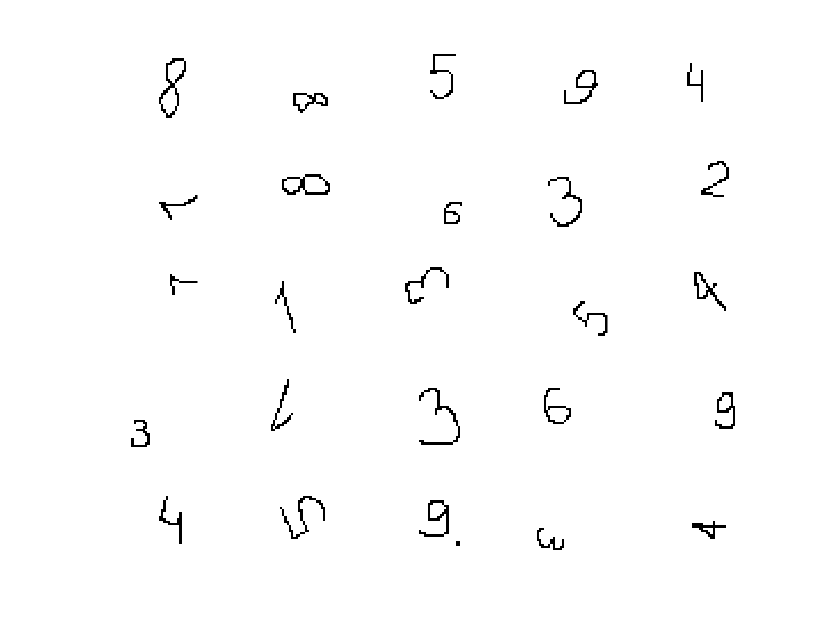

digitDatasetPath = fullfile('C:\','Users','bikhi_27b5q2u','Desktop','Предметы','4 курс','8 семестр','Интеллектуальные системы','Цифры');
imds = imageDatastore(digitDatasetPath,"IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

digitDatasetPath2 = fullfile('C:\','Users','bikhi_27b5q2u','Desktop','Предметы','4 курс','8 семестр','Интеллектуальные системы','Тестовая выборка');
imdsTest = imageDatastore(digitDatasetPath2,"IncludeSubfolders",true,"LabelSource","foldernames");

figure
numImages = length(imds.Files);
perm = randperm(numImages,25);
for i = 1:25
    subplot(5,5,i);
    imshow(imds.Files{perm(i)});
    drawnow
end

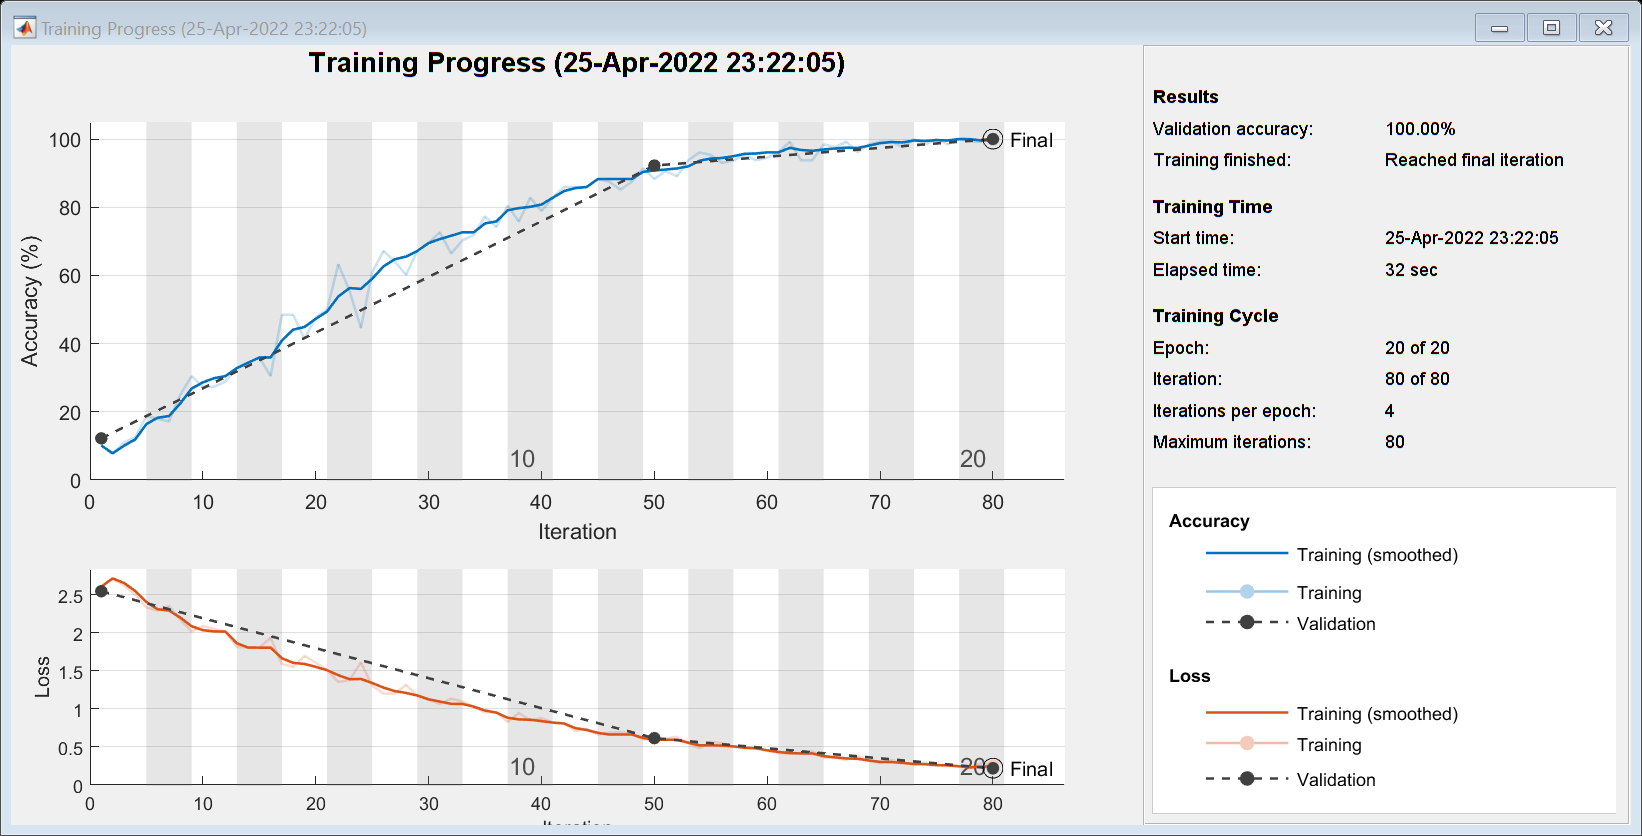


imageAugmenter = imageDataAugmenter(...
    'RandRotation',[-20 20],...
    'RandXTranslation',[-3 3],...
    'RandYTranslation',[-3 3]);
imageSize = [32 32 3];
[XTrain,~,YTrain] = digitTrain4DArrayData;
augimds = augmentedImageDatastore(imageSize,XTrain,YTrain,'DataAugmentation',imageAugmenter);

layers = [
    imageInputLayer(imageSize)
    
    convolution2dLayer(3,8,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,32,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
%     maxPooling2dLayer(2,"Stride",2)
%     
%     convolution2dLayer(3,64,'Padding',"same")
%     batchNormalizationLayer
%     reluLayer
%     
%     maxPooling2dLayer(2,"Stride",2)
%     
%     convolution2dLayer(3,128,'Padding',"same")
%     batchNormalizationLayer
%     reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

opts = trainingOptions('sgdm',...
    'MaxEpochs',20,...
    'Plots',"training-progress",...
    'Verbose',false, ...
    'Shuffle',"every-epoch",...
    'ValidationData',imdsValidation);

net = trainNetwork(imds,layers,opts);

%save net
YPred = classify(net, imdsTest);
YPredV = classify(net,imdsValidation);
YTest = imdsTest.Labels;
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9800

accuracy2 = sum(YPredV == YValidation)/numel(YValidation)

accuracy2 = 1

act = 1×1×10×600 single array
act(:,:,1,1) =

    6.6640


act(:,:,2,1) =

   -1.7074


act(:,:,3,1) =

    0.2861


act(:,:,4,1) =

   -0.6637


act(:,:,5,1) =

    0.6126


act(:,:,6,1) =

    1.8645


act(:,:,7,1) =

    1.5049


act(:,:,8,1) =

   -0.7951


act(:,:,9,1) =

   -2.6500


act(:,:,10,1) =

    2.2907


act(:,:,1,2) =

    6.0587


act(:,:,2,2) =

   -3.0120


act(:,:,3,2) =

   -2.4650


act(:,:,4,2) =

   -0.6044


act(:,:,5,2) =

    3.6746


act(:,:,6,2) =

    2.7529


act(:,:,7,2) =

   -0.5325


act(:,:,8,2) =

   -0.3528


act(:,:,9,2) =

   -1.8683


act(:,:,10,2) =

    2.4296


act(:,:,1,3) =

    4.9277


act(:,:,2,3) =

    2.1112


act(:,:,3,3) =

    0.7099


act(:,:,4,3) =

    0.1129


act(:,:,5,3) =

    1.4169


act(:,:,6,3) =

    0.1670


act(:,:,7,3) =

   -2.7095


act(:,:,8,3) =

    0.1223


act(:,:,9,3) =

   -0.8312


act(:,:,10,3) =

    0.4001


act(:,:,1,4) =

    5.8546


act(:,:,2,4) =

    2.1112


act(:,:,3,4) =

   -0.7581


act(:,:,4,